# Script to test equation

This is an equation which predicts the distribution of points in an RRT path planning problem:


$$p_{new} (x) = p_{old}(x)+p(x)\cdot\int_{x-r}^{x+r} p_{old}(\tau)d\tau+p_{old}(x-r)\cdot\int_0 ^{x-r} p(\tau)d\tau +p_{old}(x+r)\cdot\int_{x+r}^\infty p(\tau)d\tau$$


## Create a sampling distribution between 0 and 1, with 10001 points (n)

clear
close all;
n = 1001

n = 1001

x = linspace(0,1,n);
width = x(2) - x(1);

p = normpdf(x,0.5,0.4)

p =     0.4566    0.4581    0.4595    0.4609    0.4623    0.4638    0.4652    0.4666    0.4681    0.4695    0.4710    0.4724    0.4739    0.4753    0.4768    0.4782    0.4797    0.4811    0.4826    0.4840    0.4855    0.4869    0.4884    0.4898    0.4913    0.4928    0.4942    0.4957    0.4972    0.4986    0.5001    0.5016    0.5030    0.5045    0.5060    0.5075    0.5089    0.5104    0.5119    0.5134    0.5148    0.5163    0.5178    0.5193    0.5208    0.5223    0.5237    0.5252    0.5267    0.5282



pNode{1} = zeros(1, n);
r = 0.1;


## Select start and end points

pStart = 0.2;
pEnd = 0.7;

## Add 5% sampling of pEnd

pImp = zeros(1, n);
pImp(find(abs(x-pEnd))) = 0.05;
%p = p./(trapz(x,p));
p = p./sum(p);
p(find(abs(x-pEnd)<0.001)) = p(find(abs(x-pEnd)<0.001)) + 0.05/(1-width);

## Normalise p and plot

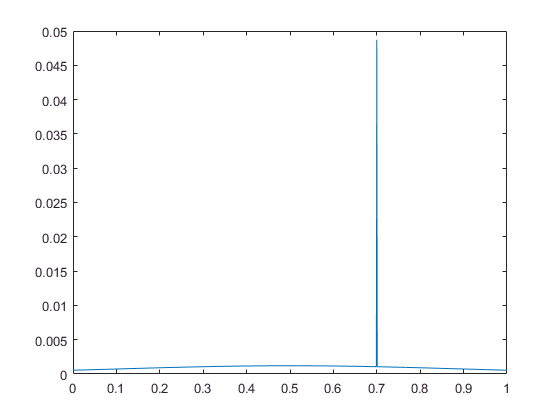

%p = p./(trapz(x,p));
p = p./sum(p);
plot(x,p);

Set starting distribution

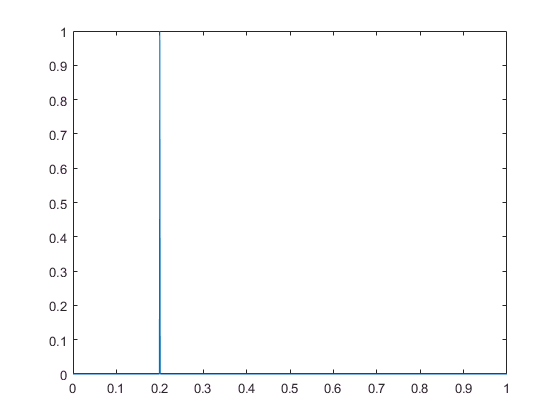

%pNode{1}(x==pStart) = 1/width;
pNode{1}(x==pStart) = 1;
plot(x, pNode{1});

## Set EX

EX(1) = pNode{1}(x==pEnd)*width;

## Loop through iterations

for k = 2:100
 

Calculate intA:


$$\int_{x-r}^{x+r}p_{old}(\tau)d\tau$$


    intA = zeros(1, n);
    for kk = 1:length(x)
        % Get limits
        xLower = max(x(kk)-r,0);
        xUpper = min(x(kk)+r,1);
        % Get limit indices:
        xLowerInd = find(abs(x-xLower)<0.001);
        xUpperInd = find(abs(x-xUpper)<0.001);
        
        % Compute integral
        %intA(kk) = trapz(x(xLowerInd:xUpperInd), pNode{k-1}(xLowerInd:xUpperInd));
        intA(kk) = distOr2(pNode{k-1}(xLowerInd:xUpperInd)');
    end
    %figure; plot(x,intA); title('intA')
    
    

Calculate intB:


$$\int_{0}^{x-r}p(\tau)d\tau$$


    
    intB = zeros(1,n);
    for kk = 1:length(x)
        % Get limits
        xLowerInd = 1;
        xUpper = max(min(x(kk)-r,1),0);
        % Get limit indices:
        xUpperInd = find(abs(x-xUpper)<0.001);
        
        % Compute integral
        if xLowerInd == xUpperInd
            intB(kk) = 0;
        else
            %intB(kk) = trapz(x(xLowerInd:xUpperInd), p(xLowerInd:xUpperInd));
            intB(kk) = distOr2(p(xLowerInd:xUpperInd)');
        end
    end
    %figure; plot(x,intB);title('intB')
    
    

Calculate intC:


$$\int_{x+r}^{\infty}p(\tau)d\tau$$


    
    intC = zeros(1,n);
    for kk = 1:length(x)
        % Get limits
        xLower = max(x(kk)+r,0);
        xUpperInd = n;
        % Get limit indices:
        xLowerInd = find(abs(x-xLower)<0.001);
        
        % Compute integral
        if xLowerInd == xUpperInd
            intC(kk) = 0;
        else
            %intC(kk) = trapz(x(xLowerInd:xUpperInd), p(xLowerInd:xUpperInd));
            %p(xLowerInd:xUpperInd)'
            intC(kk) = distOr2(p(xLowerInd:xUpperInd)');
        end
    end
    %     figure; plot(x,intC); title('intC')
    
    

Create pShiftRMinus

    shiftWidth = floor(r./width);
    pShiftRMinus = [pNode{k-1}(shiftWidth+1:end), zeros(1,shiftWidth)];
    %     figure; plot(x,pShiftRMinus);title('pShiftMinus')
    

Create pShiftRPlus

    shiftWidth = floor(r./width);
    pShiftRPlus = [zeros(1,shiftWidth), pNode{k-1}(1:end-shiftWidth)];
    %     figure; plot(x,pShiftRPlus);title('pShiftPlus')
    

Calculate pNode{k}

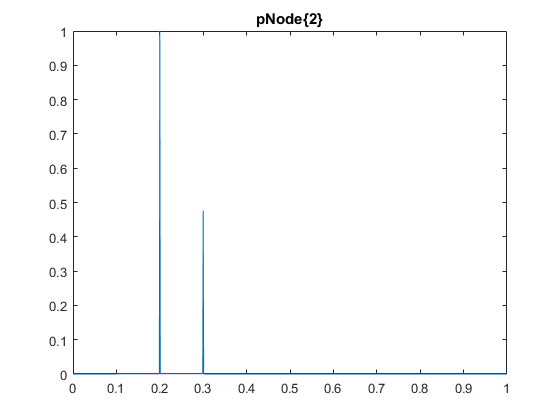

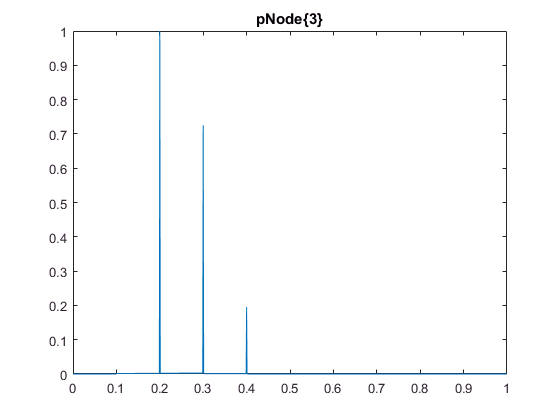

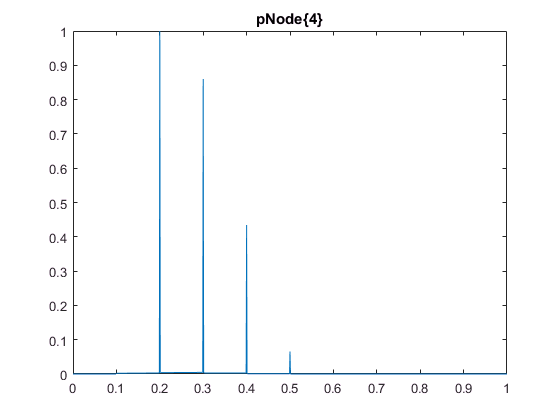

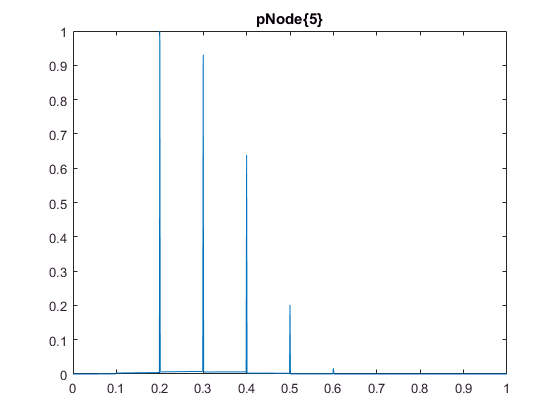

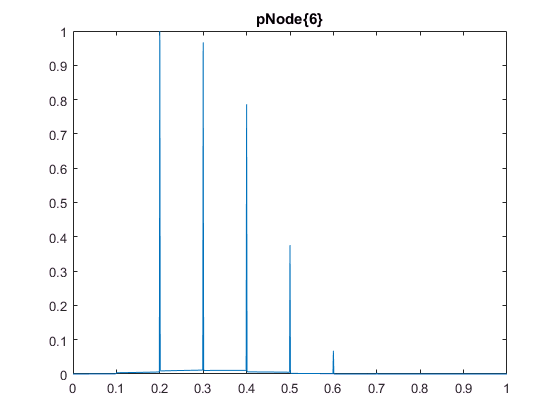

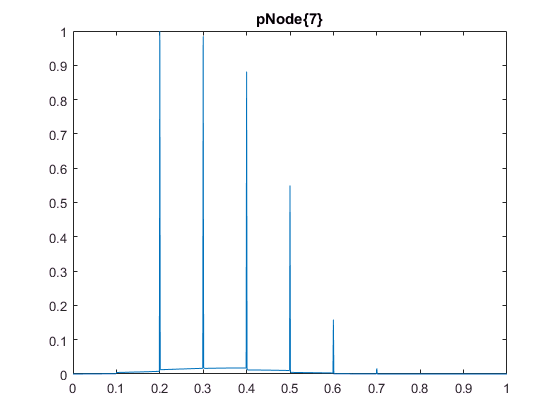

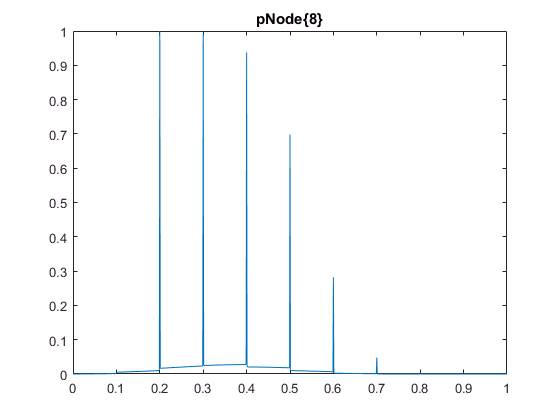

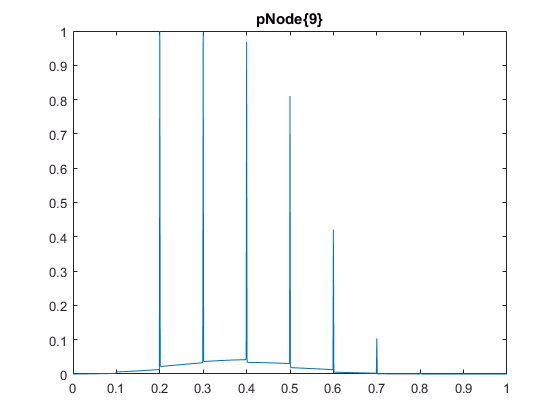

    
    %tempInt = p.*intA + pShiftRMinus.*intB + pShiftRPlus.*intC;
    % Calculate p(A U B)
    % Scale to 1 and calculate:
    %tempUnion = pNode{k-1}.*width + tempInt.*width - pNode{k-1}.*width.*tempInt.*width;
    %pNode{k} = tempUnion./width;
    pNode{k} = distOr(distOr(distOr(pNode{k-1}, p.*intA, width), pShiftRMinus.*intB, width), pShiftRPlus.*intC, width);
    %pNode{k} = distOr(pNode{k-1}, p.*intA + pShiftRMinus.*intB + pShiftRPlus.*intC, width);
    %pNode{k} = pNode{k-1} + p.*intA + pShiftRMinus.*intB + pShiftRPlus.*intC;
    %pNode{k} = p.*intA + pShiftRMinus.*intB + pShiftRPlus.*intC;
    figure;
    plot(x, pNode{k})
    title(['pNode\{',num2str(k),'\}'])
    
    % Add to running total for E[X]
    %EX(k) = EX(k-1) + k*(pNode{k}(x==pEnd)-pNode{k-1}(x==pEnd))*width;
    EX(k) = EX(k-1) + k*(pNode{k}(x==pEnd)-pNode{k-1}(x==pEnd));
    
    % Test whether pNode{k}(x==endPoint) >50%
%     if pNode{k}(x==pEnd) > 0.5/width
%         ['Expected value is ', num2str(k)]
%         break
%     end
end

EX

EX =          0         0         0         0         0    0.0187    0.1100    0.3621    0.8672    1.6713    2.7419    3.9899    5.3179    6.6472    7.9188    9.0901   10.1335   11.0345   11.7900   12.4055   12.8929   13.2683   13.5494   13.7545   13.9003   14.0013   14.0697   14.1149   14.1441   14.1627   14.1742   14.1812   14.1854   14.1879   14.1894   14.1902   14.1906   14.1909   14.1910   14.1911   14.1911   14.1912   14.1912   14.1912   14.1912   14.1912   14.1912   14.1912   14.1912   14.1912


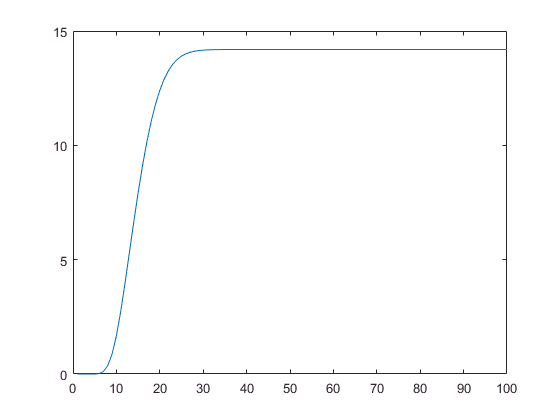

plot(EX);

## Now simulate an RRT under the same conditions

numNodes = zeros(10000,1);
for i = 1:10000
    cont = true;
    count = 1;
    pointsList = pStart;
    
    while cont
        
        % Sample a point
        sample = generateRandomPoint(p,x, pEnd, 0.05);
        
        % Find nearest node
        distancesToSample = abs(pointsList - sample);
        [closestDistance, closestNode] = min(distancesToSample);
        direction = -(pointsList(closestNode) - sample)/abs(pointsList(closestNode) - sample);
        
        % If closestDistance is less than r, add it to pointsList, else move r toward it
        if closestDistance < r
            pointsList(end+1) = round(sample, 2);
        else
            pointsList(end+1) = round(pointsList(closestNode) + direction.*r, 2);
        end
        %     figure;
        %     histogram(pointsList);
        %     title(['RRT after ', num2str(length(pointsList)), ' iterations'])
        
        if pointsList(end) == pEnd
            cont = false;
            numNodes(i) = length(pointsList);
        end
    end
end
expectedNodesRRT = mean(numNodes)

expectedNodesRRT = 14.6377